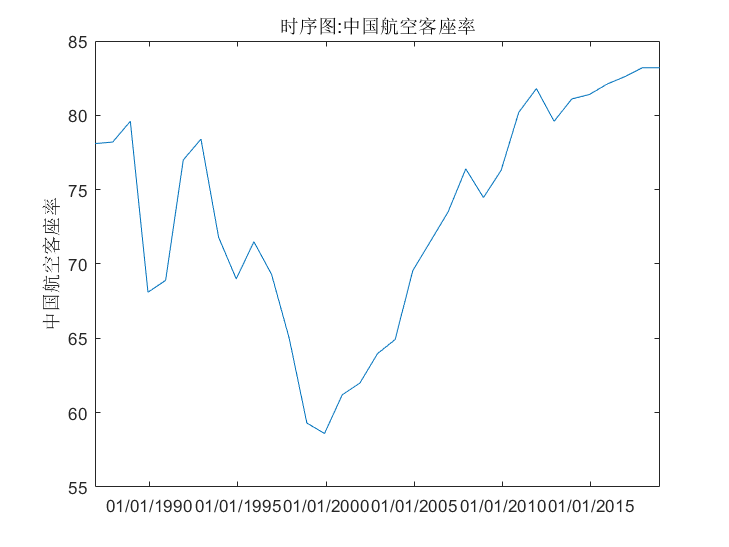

% 客座率，数据来自CEIC数据库
load_factor_data = timeseries([78.1;78.2;79.6;68.1;68.9;77;78.4;71.8;69;71.5;69.3;65;59.3;58.6;61.2;61.99;63.97;64.92;69.56;71.53;73.51;76.4;74.47;76.3;80.2;81.8;79.6;81.1;81.4;82.1;82.6;83.2;83.2], {'12/01/1986','12/01/1987','12/01/1988','12/01/1989','12/01/1990','12/01/1991','12/01/1992','12/01/1993','12/01/1994','12/01/1995','12/01/1996','12/01/1997','12/01/1998','12/01/1999','12/01/2000','12/01/2001','12/01/2002','12/01/2003','12/01/2004','12/01/2005','12/01/2006','12/01/2007','12/01/2008','12/01/2009','12/01/2010','12/01/2011','12/01/2012','12/01/2013','12/01/2014','12/01/2015','12/01/2016','12/01/2017','12/01/2018'});
load_factor_data.Name = '中国航空客座率';
load_factor_data.TimeInfo.Format = 'mm/dd/yyyy';
load_factor_data.UserData.seriesInfo = struct('seriesId','12466701','srCode','SR396726','country','China','seriesName','CN: Air: Passenger Load Factor','nameLocal','','Unit','%','frequency','Yearly','source','Civil Aviation Administration of China','firstObsDate','12/01/1986 00:00:00','LastObsDate','12/01/2018 00:00:00','multiplierCode','NA','tLastUpdTime','03/06/2019 01:19:28','seriesStatus','Active','remarks','','functionInformation','""');
plot(load_factor_data)

% 计算平均车费
avg_fee = sum(taxi_destination.cost)/length(taxi_destination.cost)

avg_fee = 104.4000

% 广州出租车基本数据，数据来自南方都市报
fuel = 5204;
turnover_without_fuel = 25243-fuel;
work_day = 30;
work_time = 8;
total_work_time = 60 * 2 * work_time * work_day;
salary_per_minute = turnover_without_fuel/total_work_time

salary_per_minute = 0.6958

% 计算司机所能容忍的最大等待时间
ideal_wait =  round(avg_fee/salary_per_minute)

ideal_wait = 150

% 取2019年9月12月23点到2019年9月13月24点的时间序列，
% 假设旅客从航班抵达到出租车上车点花费delay分钟，则
% 序列往后平移delay分钟
delay = 30

delay = 30

t1 = datetime(2019,9,12,23,0,0);
t2 = datetime(2019,9,13,23,59,59);
t = (t1:minutes(1):t2)';
t = arrayfun(@(x) x + minutes(delay),t);

% 所有航班的旅客到达出租车上车点的时刻，通过平移得到
offboard = flights_count.time;
offboard = arrayfun(@(x) x + minutes(delay),offboard);

% 旅客乘坐的士的概率，数据来自《白云机场旅客抵离方式选择研究》
taxi_rate = 0.1356

taxi_rate = 0.1356

% 旅客上车点数量，数据来自白云机场官网
exit = 6

exit = 6

% 出租车乘客上客时间（分钟），数据来自《综合客运枢纽出租车上客点管理模式和效率分析》
waste_time_per_taxi = 20/60;
taxi_per_minute = 1/waste_time_per_taxi

taxi_per_minute = 3

% 每辆出租车平均载客量，数据来自《基于时空消耗理论的多航站楼机场车道边容量评估》
person_per_taxi = 1.7

person_per_taxi = 1.7000

% 每个出口每分钟乘坐出租车离开的人数
consume_person = taxi_per_minute * person_per_taxi

consume_person = 5.1000

% 客座率，数据来自CEIC数据库，选取最近五年
load_factor = sum(load_factor_data.Data(end-4:end))/5 * 0.01

load_factor = 0.8250


% 客机平均座位数，数据来自白云机场官网2019年9月12日的所有航班的飞机型号统计
seats = sum(plane_type.seats.*plane_type.number)/sum(plane_type.number);
% 每个出口的人数
person_per_flight = seats * load_factor / exit

person_per_flight = 27.6548

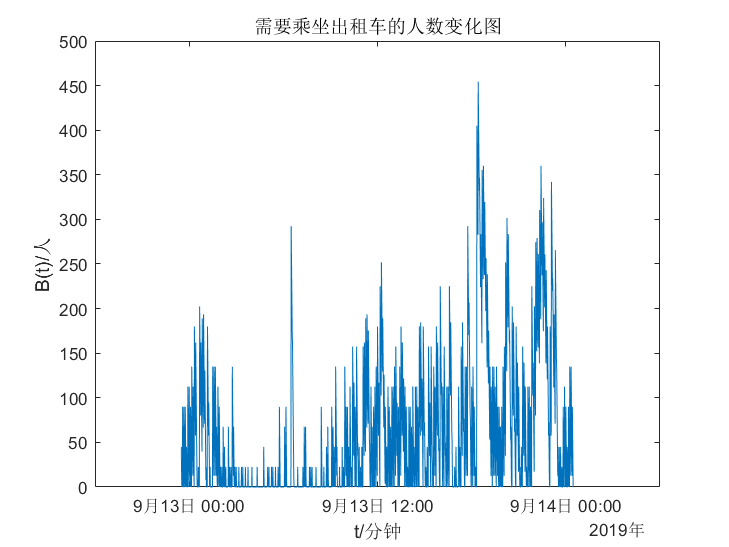


taxi_intended_per_minute = zeros(length(t),1);
result = zeros(length(t),1);

% 每个出口的需要乘坐出租车的人数
taxi_intended_per_flight = taxi_rate*person_per_flight;
% 第一分钟的需要乘坐出租车的人数
result(1) = taxi_intended_per_flight * flights_count.flights(1);
taxi_intended_per_minute(1) = taxi_intended_per_flight * flights_count.flights(1);
% 计算第二分钟以后的需要乘坐出租车的人数
for i = 2:length(t)
    if result(i-1) - consume_person < 0
        
        result(i) = 0;
    else
        result(i) = result(i-1) - consume_person;
    end
    if find(offboard==t(i))
        index = find(offboard==t(i));
        result(i) = result(i) + taxi_intended_per_flight * flights_count.flights(index);
        taxi_intended_per_minute(i) = taxi_intended_per_flight * flights_count.flights(index);
    end
    
end

% 需要乘坐出租车的人数随时间变化图
plot(t,result)
title('排队区等候乘出租车的人数变化图')
ylabel('Y(t)/人')
xlabel('t/分钟')

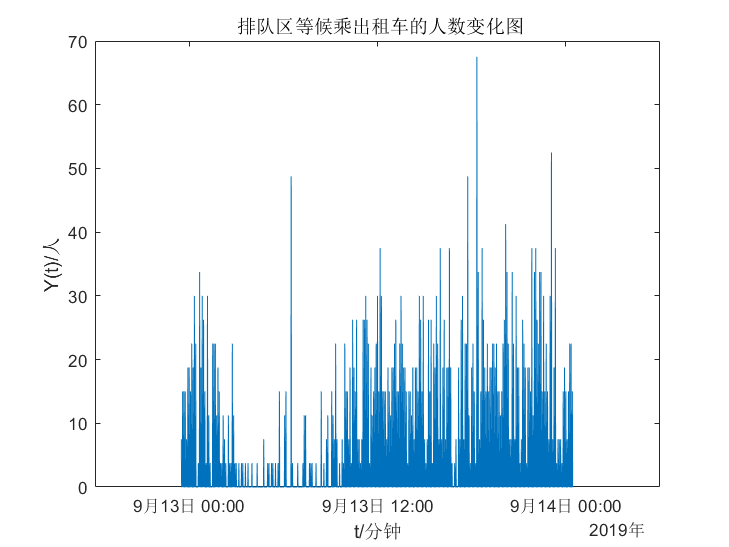

% 每分钟需要乘坐出租车的人数图
plot(t,taxi_intended_per_minute.*exit)
title('需要乘坐出租车的人数变化图')
ylabel('B(t)/人')
xlabel('t/分钟')

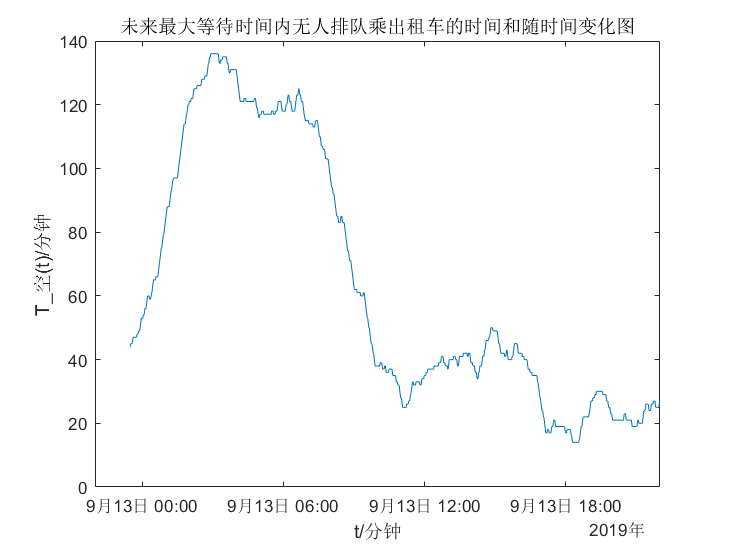

% 计算未来最大等待时间内，无人排队乘出租车的时间
t_blank = zeros(length(t)-ideal_wait,1);
for i = 1:length(t)-ideal_wait
    t_blank(i) = 0;
    for j = 1:ideal_wait
        if result(i+j)==0
            t_blank(i) = t_blank(i) + 1;
        end
    end
end

% 未来最大等待时间内，无人排队乘出租车的时间随时间变化图
plot(t(1:length(t_blank)),t_blank)
title('未来最大等待时间内无人排队乘出租车的时间和随时间变化图')
ylabel('T_空(t)/分钟')
xlabel('t/分钟')

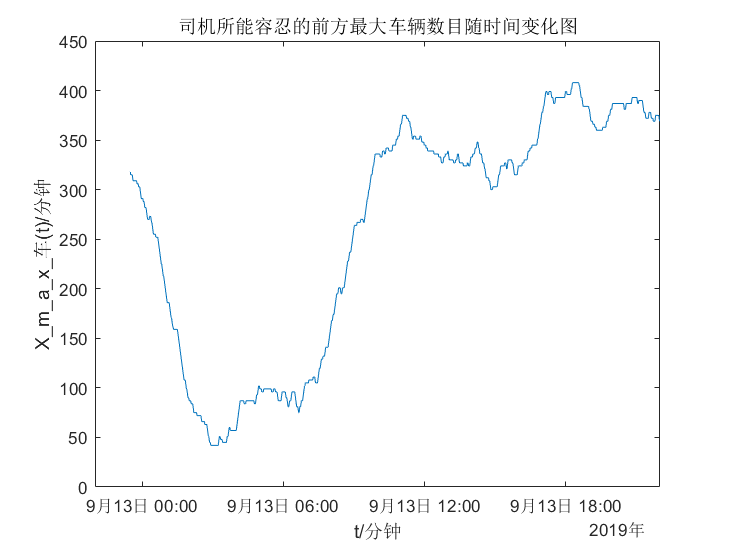

% 计算司机所能容忍的最大车辆数目
ideal_taxi_number = (ideal_wait - t_blank) /  waste_time_per_taxi;
plot(t(1:length(ideal_taxi_number)),ideal_taxi_number)
title('司机所能容忍的前方最大车辆数目随时间变化图')
ylabel('X_m_a_x_车(t)/分钟')
xlabel('t/分钟')

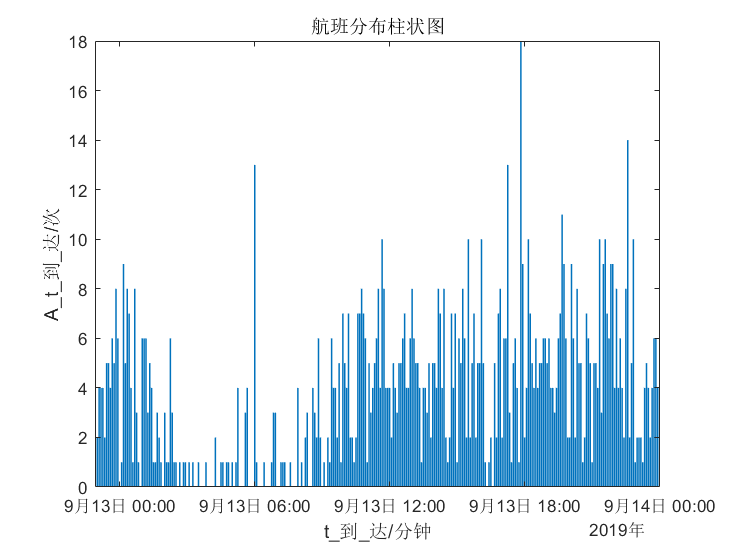

% 航班柱形图
bar(flights_count.time,flights_count.flights)
title('航班分布柱状图')
ylabel('A_t_到_达/次')
xlabel('t_到_达/分钟')

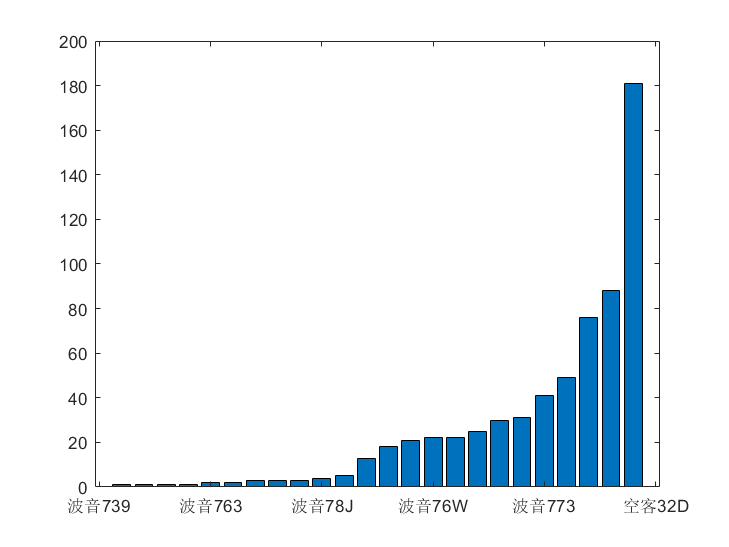

% 飞机型号
bar(plane_type.number)
set(gca,'xticklabel',plane_type.type)